clear
path = '/Users/jorgeaugustomartinezortiz/Library/CloudStorage/OneDrive-BaylorUniversity/CASPER/projects/plasma_crystal/crystal_analysis/crystal_videos/laser_pulse_06102022.avi';
video = VideoReader(path)

video =   VideoReader with properties:

   General Properties:
            Name: 'laser_pulse_06102022.avi'
            Path: '/Users/jorgeaugustomartinezortiz/Library/CloudStorage/OneDrive-BaylorUniversity/CASPER/projects/plasma_crystal/crystal_analysis/crystal_videos'
        Duration: 116.3999
     CurrentTime: 0
       NumFrames: 3492

   Video Properties:
           Width: 1280
          Height: 1024
       FrameRate: 30.0000
    BitsPerPixel: 8
     VideoFormat: 'Grayscale'


### Video Cropping

index = 100;

%% VIDEO CROPPING
crop.leftCrop = 200;
crop.rightCrop = 120;
crop.upperCrop = 200;
crop.lowerCrop = 200;

img = displayFrame(video,index,[crop.leftCrop crop.rightCrop],[crop.upperCrop crop.lowerCrop]);

### Video Filtering

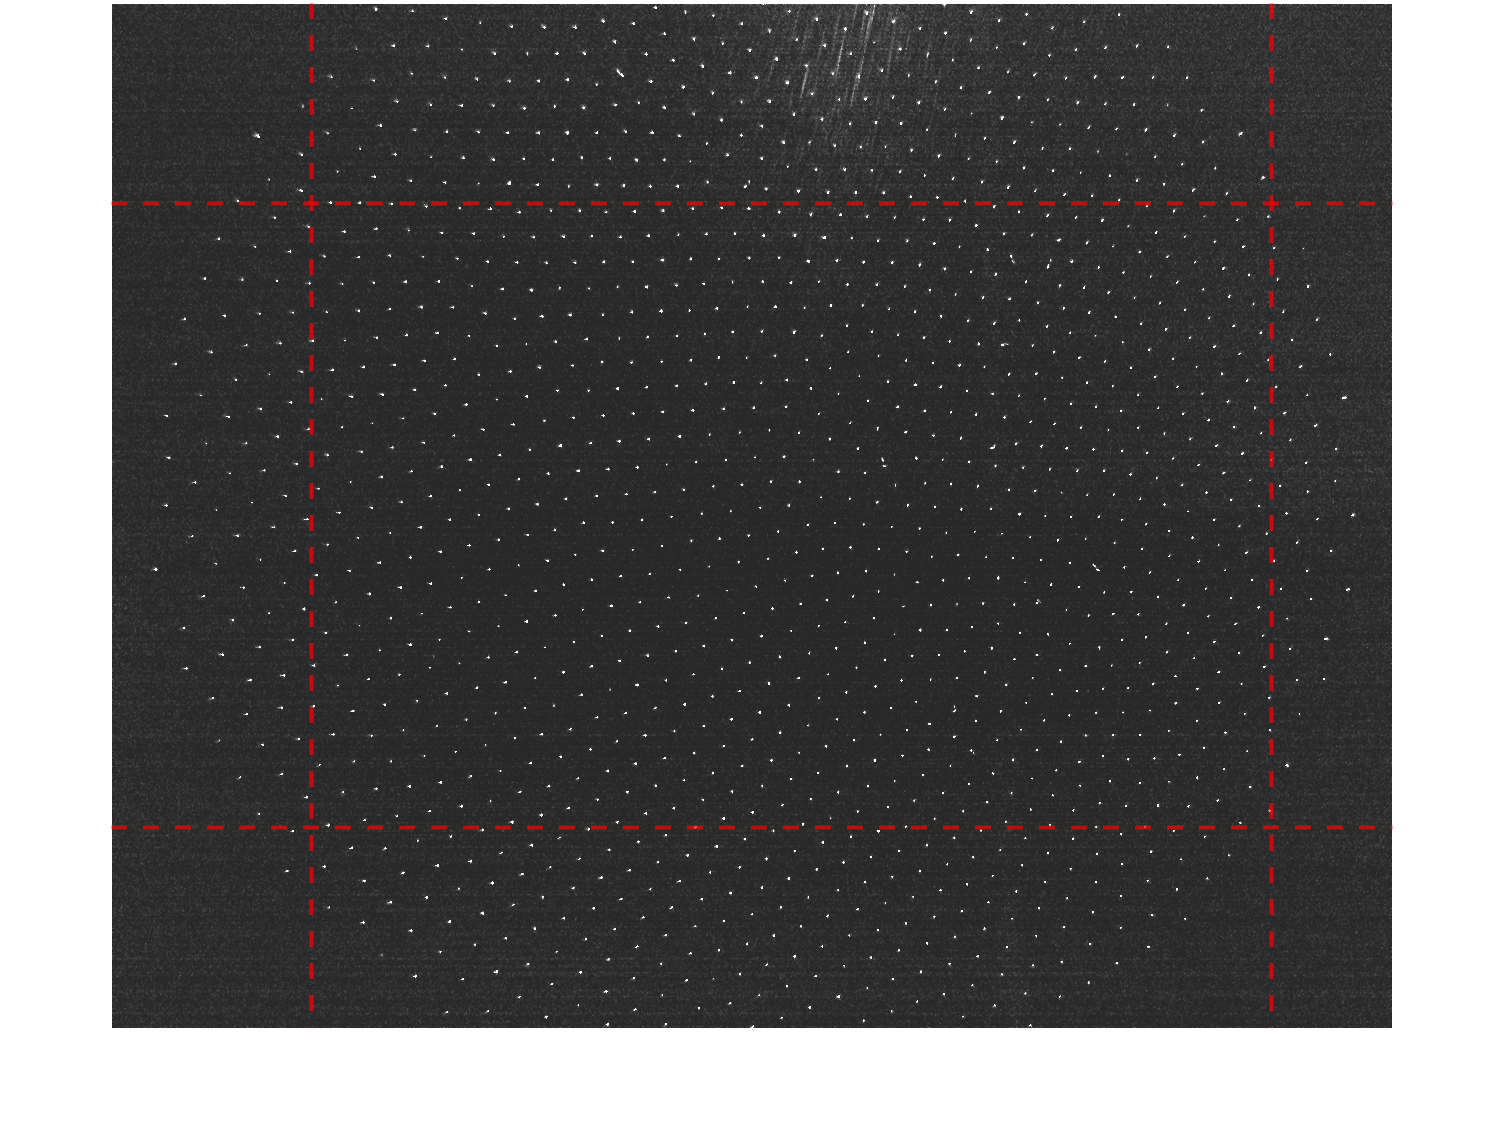

gaussFilt.sigma_BG = 50;
frame = getFrame(video,index);

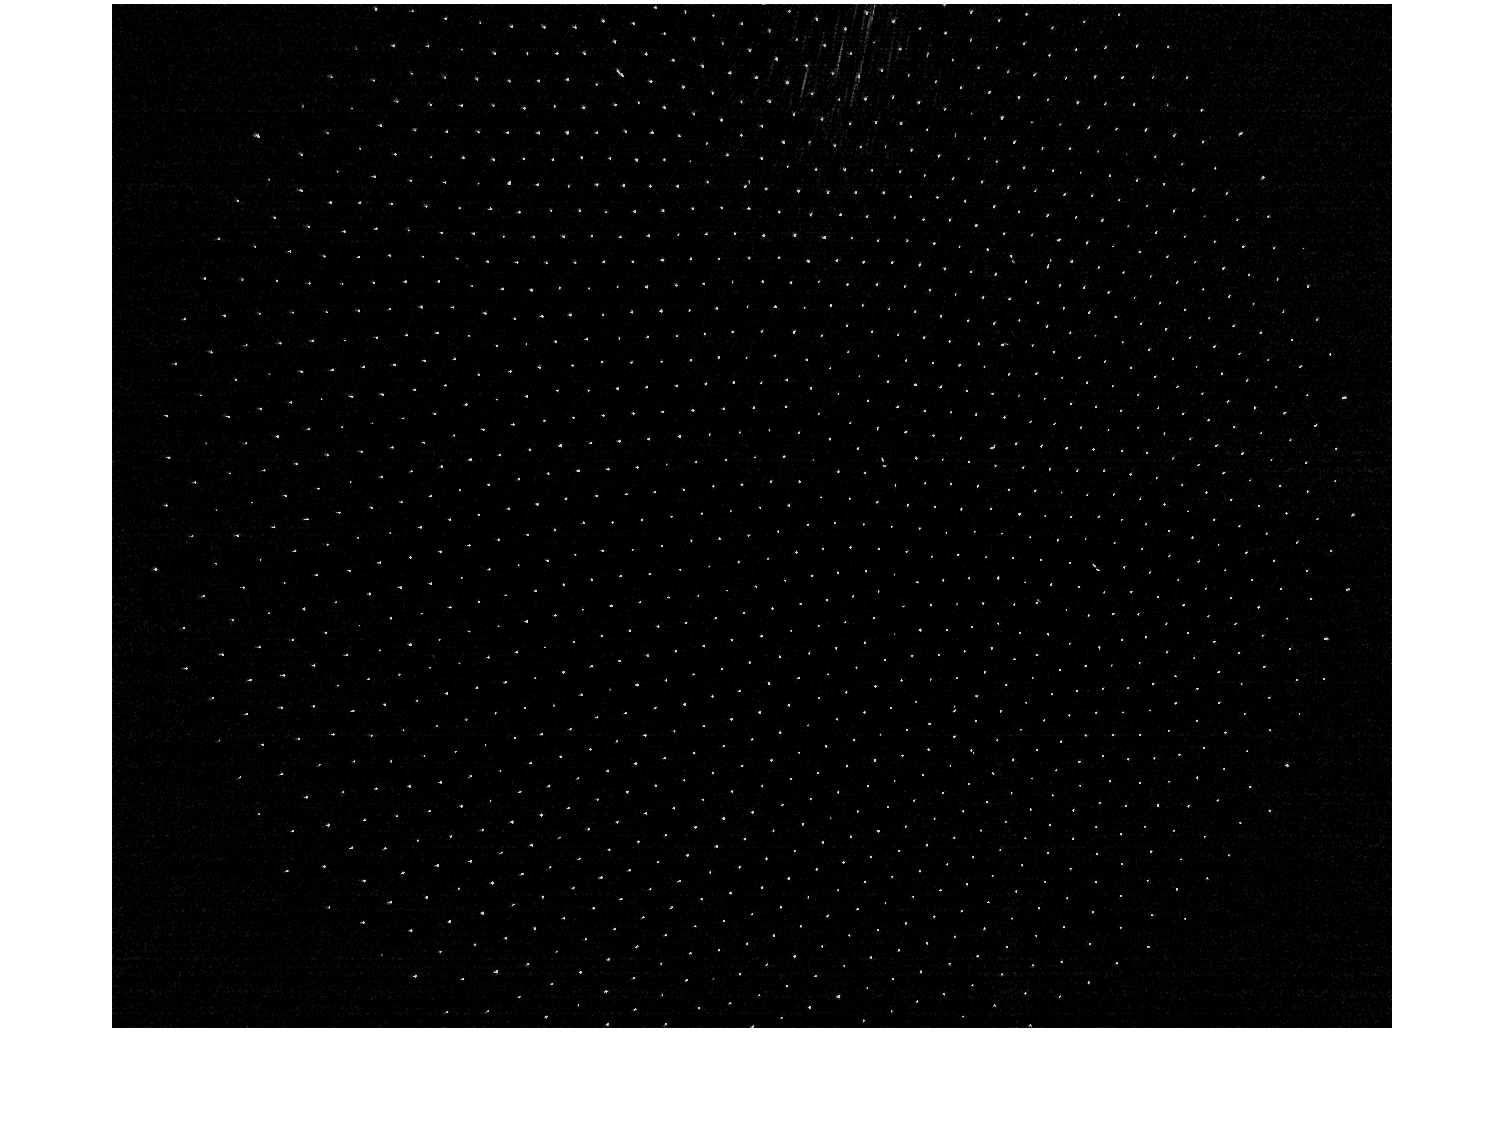

BG = imgaussfilt(frame,gaussFilt.sigma_BG);
frameFilt = imsubtract(frame,BG);
imshow(frameFilt)

### Process the video and save

video_filtered = VideoWriter([video.Path '/crop.avi'],'Grayscale AVI');
processVideo(video_filtered,video,crop,gaussFilt);

Processing batch (1/18)...
Done.
Progress: 5.73%
Processing batch (2/18)...
Done.
Progress: 11.45%
Processing batch (3/18)...
Done.
Progress: 17.18%
Processing batch (4/18)...
Done.
Progress: 22.91%
Processing batch (5/18)...
Done.
Progress: 28.64%
Processing batch (6/18)...
Done.
Progress: 34.36%
Processing batch (7/18)...
Done.
Progress: 40.09%
Processing batch (8/18)...
Done.
Progress: 45.82%
Processing batch (9/18)...
Done.
Progress: 51.55%
Processing batch (10/18)...
Done.
Progress: 57.27%
Processing batch (11/18)...
Done.
Progress: 63.00%
Processing batch (12/18)...
Done.
Progress: 68.73%
Processing batch (13/18)...
Done.
Progress: 74.46%
Processing batch (14/18)...
Done.
Progress: 80.18%
Processing batch (15/18)...
Done.
Progress: 85.91%
Processing batch (16/18)...
Done.
Progress: 91.64%
Processing batch (17/18)...
Done.
Progress: 97.37%
Processing batch (18/18)...
Done.
Progress: 100.00%


function frame = getFrame(video,idx)
    if idx > video.NumFrames
        warning('Index outside valid range (0-%i). Reading last frame instead',video.NumFrames);
        idx = video.NumFrames-1;
    end

    video.CurrentTime = (1/video.FrameRate) * idx;
    frame = readFrame(video);
end

function stack = readFrameStack(video,vec)
    firstFrame = vec(1);
    lastFrame = vec(2);

    numFrames = lastFrame - firstFrame;
    stack = zeros(video.Height,video.Width,numFrames,'uint8');

    video.CurrentTime = firstFrame * (1/video.FrameRate);
    for i = 1:numFrames
        stack(:,:,i) = readFrame(video);
    end
end

function processVideo(videoWriter,videoReader,crop,gaussFilt)
    % Function Prologue
    batchSize = 200;
    heightCrop = 1+crop.upperCrop:(videoReader.Height-crop.lowerCrop);
    widthCrop = 1+crop.leftCrop:(videoReader.Width-crop.rightCrop);

    % Open the new video writer object
    open(videoWriter);

    % Determine the number of batches necessary to process the video
    numBatch = ceil(videoReader.NumFrames/batchSize);

    for i = 0:numBatch-1
        fprintf("Processing batch (%i/%i)...\n",i+1,numBatch);
        % Determine the ranges to be processed
        firstFrame = i * batchSize;
        if i == numBatch-1
            lastFrame = videoReader.NumFrames;
        else
            lastFrame = firstFrame + batchSize;
        end

        % Read frames
        stack = readFrameStack(videoReader,[firstFrame lastFrame]);

        % Crop Video
        stack = stack(heightCrop,widthCrop,:);

        % Filter frames
        BG = imgaussfiltStack(stack,gaussFilt.sigma_BG);
        stack = imSubtract(stack,BG);

        % WriteFrames to Video 
        writeVideo(videoWriter,stack);

        fprintf("Done.\n")
        fprintf("Progress: %.2f%%\n",lastFrame/videoReader.NumFrames*100)
    end

    % Close video writer object
    close(videoWriter);
end

function img = displayFrame(video,idx,varargin)
    x_vec = [];
    y_vec = [];
    xcrop = false;
    ycrop = false;
    cropFormat = '--r';

    % INPUT VALIDATION
    if nargin > 2
        if nargin ~= 4
            error('Error: invalid number of input arguments')
        end

        x_vec = varargin{1};
        y_vec = varargin{2};

        % Validate x dimension
        if ~isempty(x_vec)
            x_max = max(x_vec(1),x_vec(2));

            if (0 <= x_max) && (x_max <= video.Width) && ((x_vec(1)+x_vec(2)) < video.Width)
                xcrop = true;
            else 
                error('Invalid range in x dimension (0,%i)',video.Width)
            end
        end
    

        % Validate y dimension
        if ~isempty(y_vec) 
            y_max = max(y_vec(1),y_vec(2));

            if (0 <= y_max) && (y_max <= video.Width) && ((y_vec(1)+y_vec(2)) < video.Height)
                ycrop = true;
            else
                error('Invalid crop in y dimension (0,%i)',video.Height)
            end
        end
    end

    img = imshow(getFrame(video,idx));
    if xcrop
        xline([x_vec(1) (video.Width-x_vec(2))],cropFormat,'LineWidth',2)
    end

    if ycrop
        yline([y_vec(1) (video.Height-y_vec(2))],cropFormat,'LineWidth',2)
    end
end

function playVideo(video,varargin)
    x_vec = varargin{1};
    y_vec = varargin{2};

    i = 0;
    img = displayFrame(video,0,x_vec,y_vec);
    while i < video.NumFrames
        img.CData = getFrame(video,i);
        drawnow
        pause(4/video.FrameRate);
        i = i+1;
    end
end

% VIDEO FILTERING FUNCTIONS
function stackFiltered = imgaussfiltStack(stack,sigma)
    numFrames = size(stack,3);
    stackFiltered = zeros(size(stack),class(stack));

    for i = 1:numFrames
        stackFiltered = imgaussfilt(stack(:,:,i),sigma);
    end
end

function stackSub = imSubtract(stackA,stackB)
    stackSub = stackA - stackB;
    idx = stackSub < 0;
    stackSub(idx) = 0;
end